clear
clc
close all

BandTestData=importdata("BandTestData.mat");
MetrTestData=importdata("MetricTestData.mat");
band_mdl=importdata("band_model.mat");
band_mdl=band_mdl.band_model;
metr_mdl=importdata('metric_model.mat');
metr_mdl=metr_mdl.metric_model;

Error=table();
GT=nmz(MetrTestData.GT);
MetrNames=MetrTestData.Properties.VariableNames;
for i=1:width(MetrTestData)-1
    ColBuf=MetrTestData.(char(MetrNames(i)));
    ColBuf(isinf(ColBuf))=nan;
    ColBuf=nmz(ColBuf);
    Error.(char(MetrNames(i)))=mse(ColBuf,GT,'omitnan');
end

MetrPred=nmz(predict(metr_mdl,MetrTestData));
BandPred=nmz(predict(band_mdl,BandTestData));
Error.MetrMdl=mse(MetrPred,GT);
Error.BandMdl=mse(BandPred,GT);

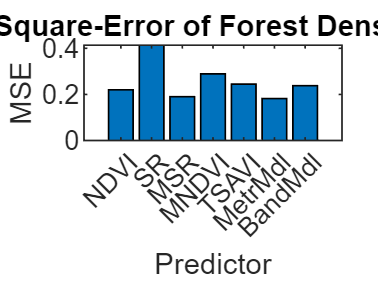

bar(table2array(Error(1,:)))
set(gca,'xticklabel',Error.Properties.VariableNames)
ylabel('MSE')
xlabel('Predictor')
title('Normalized Mean-Square-Error of Forest Density Prediction Models')

function data_n=nmz(d)
    data_n=(d-min(d))./(max(d)-min(d));
end